# Práctica 6. Fórmulas de diferenciación e integración numérica.

## Implementar métodos de aproximación de derivadas e integrales y aplicarlos para comprobar su orden.

**a)** Para una función $f:\mathbb{R} \longrightarrow \mathbb{R}$, un punto $x\in\mathbb{R}$ y un paso pequeño $h\in\mathbb{R}$, deseamos obtener una aproximación de su derivada $f^\prime(x)$. Para ello utilizaremos la fórmula de segundo orden. Lo implementaremos en el **APÉNDICE A**.

                                    
$$f^\prime(x) \approx \frac{f(x+h)-f(x-h)}{2h}$$


La función nos debe devolver, dados $f$, $x$ y $h$:

- El valor $D$ aproximado de la derivada $f^\prime (x)$.

**b)** Para una función $f:\mathbb{R} \longrightarrow \mathbb{R}$, un intervalo $[a,b]\in\mathbb{R}$ y un natural $m\in\mathbb{N}$, deseamos obtener una aproximación de su integral por la fórmula del trapecio compuesta en $[a,b]$. Lo implementaremos en el **APÉNDICE B**.

                                  
$$\int_a^b f(x) dx \approx \frac{h}{2} \left(f(a) + 2\sum_{i=1}^{m-1}f(a+ih)+f(b) \right)$$


La función nos debe devolver, dados $f$, $a$, $b$ y $m$:

- El valor $I$ de la integral aproximada por la fórmula del trapecio compuesta.

**c)** Para una función $f:\mathbb{R} \longrightarrow \mathbb{R}$, un intervalo $[a,b]\in\mathbb{R}$ y un natural $m\in\mathbb{N}$, deseamos obtener una aproximación de su integral por la fórmula de Simpson compuesta en $[a,b]$. Lo implementaremos en el **APÉNDICE C**.

                
$$\int_a^b f(x) dx \approx \frac{h}{3} \left(f(a) + 4\sum_{i=1}^m f(a+(2i-1)h) + 2\sum_{i=1}^{m-1}f(a+2ih)+f(b) \right)$$


La función nos debe devolver, dados $f$, $a$, $b$ y $m$:

- El valor $I$ de la integral aproximada por la fórmula de Simpson compuesta.

**d)** Aproxima el valor de la derivada $f^\prime\left(\sqrt{\frac{\pi}{2}}\right)$ siendo $f$ la función $f(x)=\sin(x^2)$.

f = @(x)sin(x.^2);
x = sqrt(pi/2);
D = diffCentrada(f,x,0.1)

D = -0.0248

Ahora aproxima el valor de la misma derivada con pasos $h=[10^{-1},10^{-2},10^{-3},10^{-4}]$ y rellena el siguiente código para comprobar el orden del método.

A=zeros(4,3); 
%Rellena en la columna 1 de esta matriz los pasos, en la columna 2 el error de la
%aproximación y en la columna 3 el cociente error/(h^2).
A(:,1) = 10.^-(1:4);
D = diffCentrada(f,x,A(:,1));
A(:,2) = abs(D); %f'(x) = 2xcos(x^2) -> f'(sqrt(pi/2)) = 0 -> error = |D - 0|
A(:,3) = A(:,2) ./ (A(:,1).^2);
%Cabecera de la Tabla
t3='      h     ';
t4='  error ';
t5=' error/h^2';
l1='--------';
l2='------';
l3='----------';
l3b='   ----------';
l4='    ------------';

%Tabla con cabecera
fprintf('%11s %12s %14s \n',t3,t4,t5,l3,l3b,l4) 

      h            error       error/h^2 
 ----------    ----------     ------------ 


fprintf('%12.6e %14.6e %14.6e \n',A.')

1.000000e-01   2.480420e-02   2.480420e+00 
1.000000e-02   2.506366e-04   2.506366e+00 
1.000000e-03   2.506626e-06   2.506626e+00 
1.000000e-04   2.506662e-08   2.506662e+00 


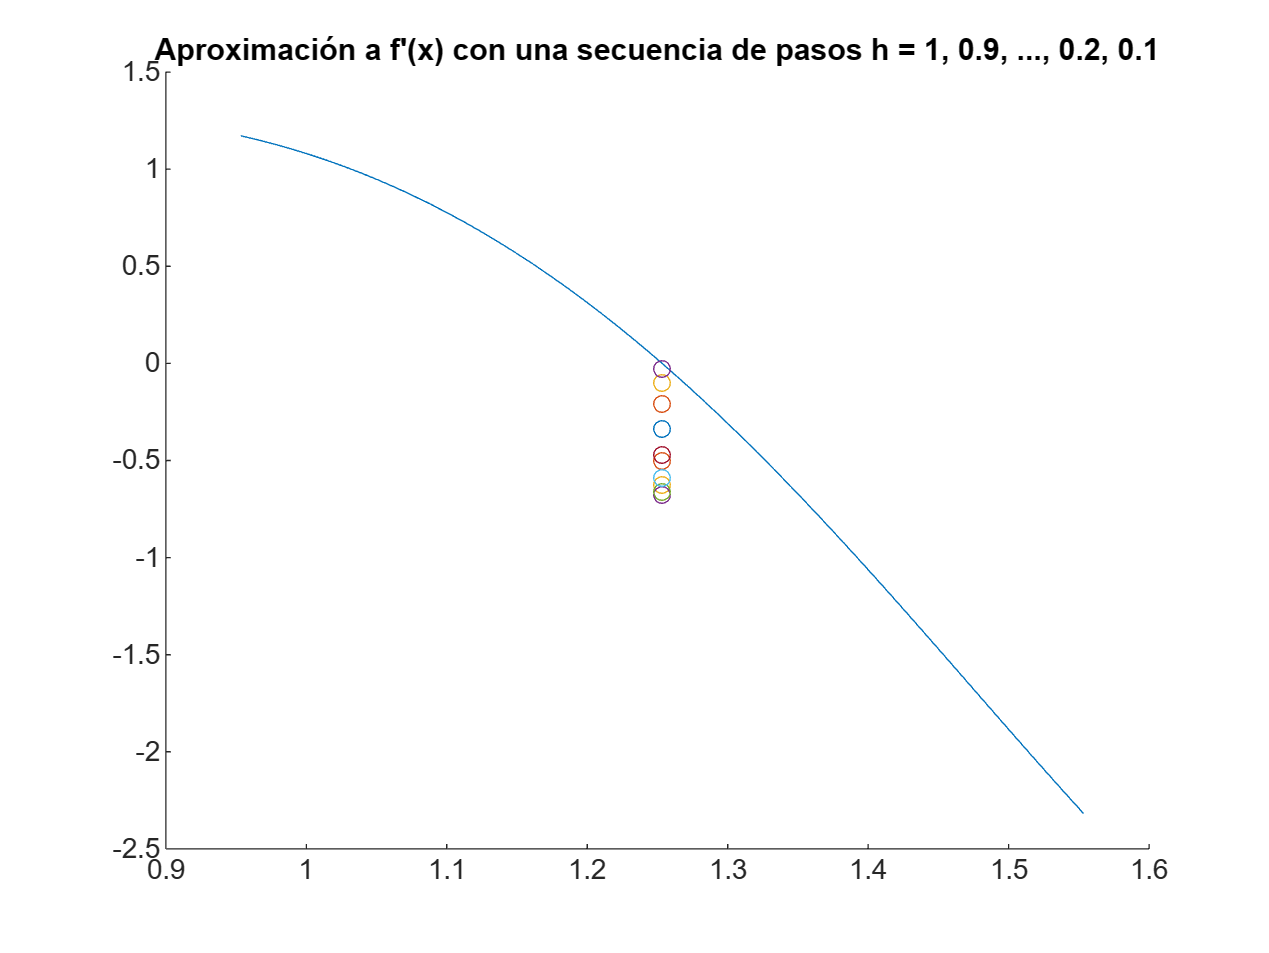

% El órden del método es 2, pues al dividir entre h^2 el error relativo se
% mantiene aproximadamente constante
z = linspace(x-0.3,x+0.3,50);
df = @(x) 2.*x .* cos(x.^2);
hold on
plot(z,df(z))
scatter(x,diffCentrada(f,x,(1:-0.1:0.1)))
title("Aproximación a f'(x) con una secuencia de pasos h = 1, 0.9, ..., 0.2, 0.1")
hold off

**e)** Aproxima el valor de la integral $\int_0^\pi sin(x) \, dx$ por ambos métodos que has implementado. Para el método del trapecio, hazlo para $m=[3,31,310,3100]$ y rellena el siguiente código para comprobar el orden del método.


$$\int_0^{\pi \;} \sin \left(x\right)\;\mathrm{dx}=-\cos \left(x\right){\left.\right\rbrack }_0^{\pi \;} =1-\left(-1\right)=2$$


A=zeros(4,3); 
%Rellena en la columna 1 de esta matriz los pasos, en la columna 2 el error de la
%aproximación y en la columna 3 el cociente error/(h^2).
a = 0; b = pi; m = [3,31,310,3100];
I = zeros(4,1);
f = @(x)sin(x);
for i = 1:4
    I(i) = integTrapecio(f,a,b,m(i));
end
A(:,1) = (b - a)./m;
A(:,2) = abs(I - 2);
A(:,3) = A(:,2) ./ (A(:,1).^2);

%Cabecera de la Tabla
t3='      h     ';
t4='  error ';
t5=' error/h^2';
l1='--------';
l2='------';
l3='----------';
l3b='   ----------';
l4='    ------------';

%Tabla con cabecera
fprintf('%11s %12s %14s \n',t3,t4,t5,l3,l3b,l4) 

      h            error       error/h^2 
 ----------    ----------     ------------ 


fprintf('%12.6e %14.6e %14.6e \n',A.')

1.047198e+00   1.862006e-01   1.697946e-01 
1.013417e-01   1.711983e-03   1.666952e-01 
1.013417e-02   1.711693e-05   1.666670e-01 
1.013417e-03   1.711690e-07   1.666667e-01 


% El órden del método es 2, pues al dividir entre h^2 el error relativo se
% mantiene aproximadamente constante

Para el método de Simpson, hazlo para $m=[2,10,100,1000]$ y rellena el siguiente código para comprobar el orden del método

A=zeros(4,3); 
%Rellena en la columna 1 de esta matriz los pasos, en la columna 2 el error de la
%aproximación y en la columna 3 el cociente error/(h^4).

%Escribe aquí tu código
m = [2,10,100,1000];
for i = 1:4
    I(i) = integSimpson(f,a,b,m(i));
end
A(:,1) = (b-a)./(2.*m);
A(:,2) = abs(I - 2);
A(:,3) = A(:,2)./(A(:,1).^4);

%Cabecera de la Tabla
t3='      h     ';
t4='  error ';
t5=' error/h^4';
l1='--------';
l2='------';
l3='----------';
l3b='   ----------';
l4='   ------------';

%Tabla con cabecera
fprintf('%11s %12s %14s \n',t3,t4,t5,l3,l3b,l4) 

      h            error       error/h^4 
 ----------    ----------    ------------ 


fprintf('%12.6e %14.6e %14.6e \n',A.')

7.853982e-01   4.559755e-03   1.198345e-02 
1.570796e-01   6.784442e-06   1.114383e-02 
1.570796e-02   6.764718e-10   1.111144e-02 
1.570796e-03   6.838974e-14   1.123341e-02 


% El órden del método es 4, pues al dividir entre h^4 el error relativo se
% mantiene aproximadamente constante

### Apéndice A. Diferenciación numérica.

function D = diffCentrada(f,x,h)
   assert(all(h ~= 0));
   D = (f(x+h) - f(x-h)) ./ (2.*h);
end

### Apéndice B. Fórmula del trapecio


$$\int_a^b f(x) dx \approx \frac{h}{2} \left(f(a) + 2\sum_{i=1}^{m-1}f(a+ih)+f(b) \right)$$


function I = integTrapecio(f,a,b,m)
    assert(a <= b && m > 0);
    h = (b - a) / m;
    I = (h/2) * (f(a) + f(b) + 2*sum(f(a + (1:m-1).*h)));
end

### Apéndice C. Fórmula de Simpson


$$\int_a^b f(x) dx \approx \frac{h}{3} \left(f(a) + 4\sum_{i=1}^m f(a+(2i-1)h) + 2\sum_{i=1}^{m-1}f(a+2ih)+f(b) \right)$$


function I = integSimpson(f,a,b,m)
    assert(m > 0 && a <= b);
    h = (b - a)/(2*m);
    I = h/3*(f(a) + 4.*sum(f(a + (2.*(1:m)-1).*h)) + 2.*sum(f(a + 2.*(1:m-1).*h)) + f(b));
end